Goal is to take trackmate tracks and overlay them on the kymograph to see how well tracking works for analysing speeds and trajectories

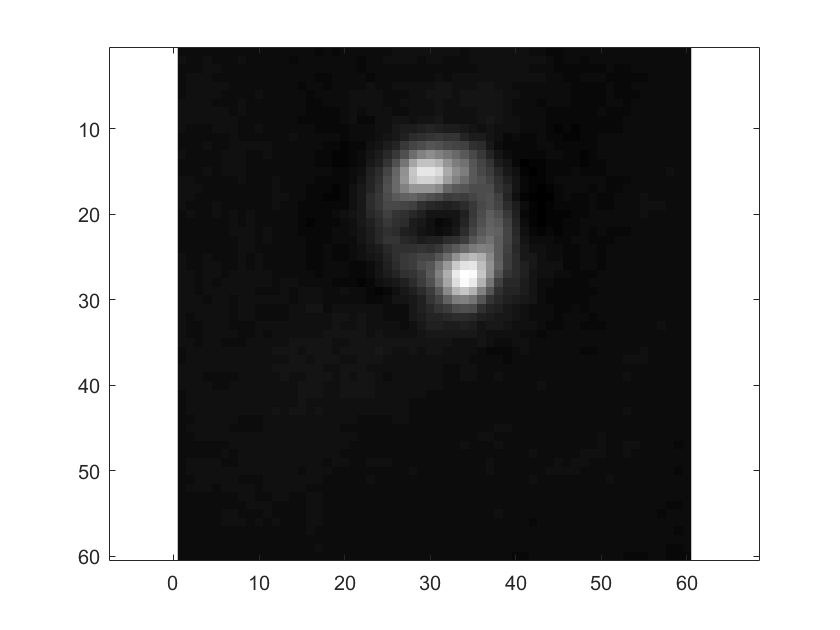

fname_tracks = 'analysed/180327_Sam1_1mW_RingHiLO_2_MMStack_Pos0_Tracks.xml';
fname_kymo = 'analysed/180327_Sam1_1mW_RingHiLO_2_MMStack_Pos0.ome_denoise_reg_ring11_kymo.tif';
fname_fit = 'analysed/180327_Sam1_1mW_RingHiLO_2_MMStack_Pos0.ome_denoise_reg_ring11_fitData.mat';
fname_im = 'analysed/180327_Sam1_1mW_RingHiLO_2_MMStack_Pos0.ome_denoise_reg_ring11_bgsub.tif';
clipz=true;
[tracks, metadata] = importTrackMateTracks(fname_tracks,clipz);
imS = imreadstack(fname_im);

im = imS(:,:,1);
figure;
imagesc(im);
colormap('gray');
axis equal;

test plot all the tracks

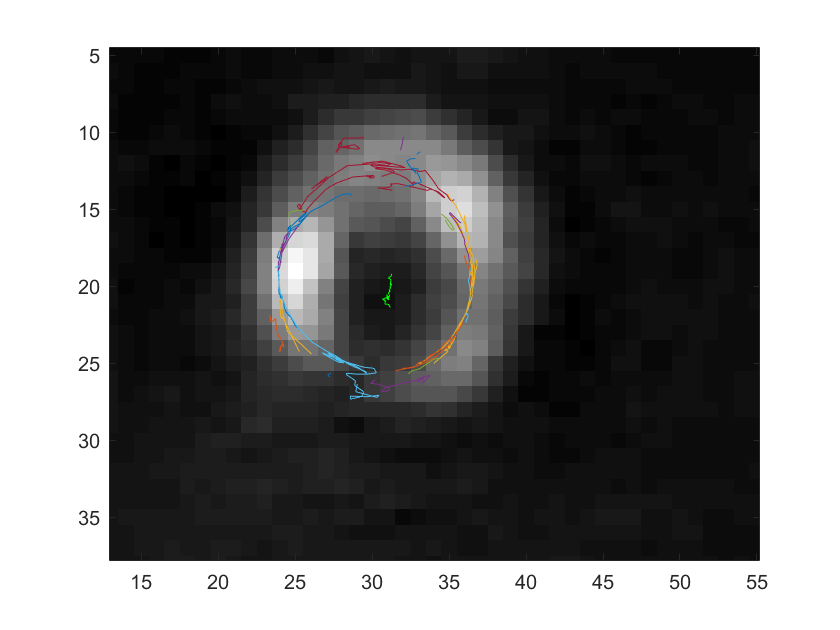

im = imS(:,:,end);
figure;
figure;
imagesc(im);
colormap('gray');
axis equal;
hold all;

pixSz = 0.065;
nTrack = numel(tracks);
for ii = 1:nTrack
    tr = tracks{ii};
    xPix = tr(:,2)/pixSz;
    yPix = tr(:,3)/pixSz;
    plot(xPix,yPix,'-');
end

%plot the ring centre

data = load(fname_fit);
circFit = data.circFit;
nFr = numel(circFit);
for ii = 1:nFr
    x0(ii) = circFit{ii}.z(1);
    y0(ii) = circFit{ii}.z(2);
    r0(ii) = circFit{ii}.r;
end
plot(x0,y0,'g-');
xlim([12.9 55.2])
ylim([4.5 37.8])

Can we look at a few per frame examples to see if the pix centre is ok?

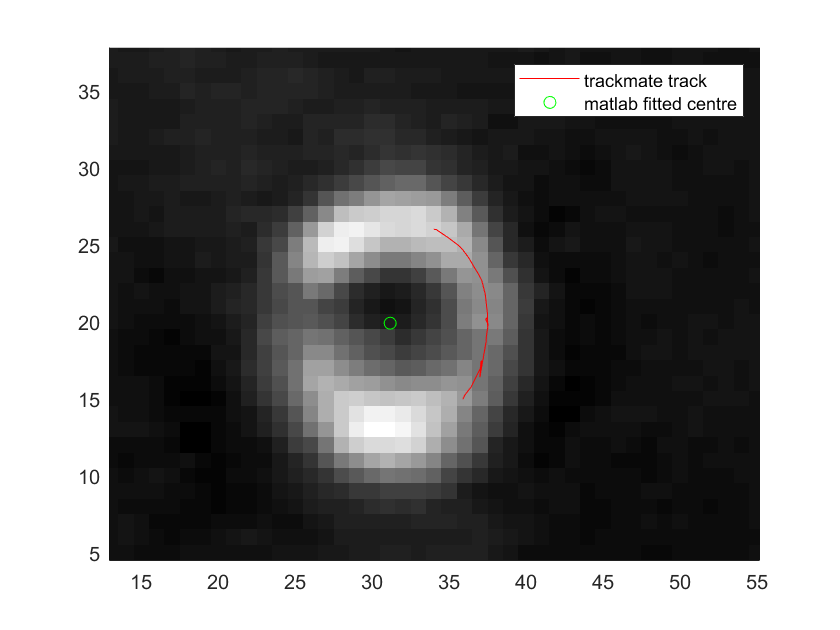

figure;hold all;
exampleTrackNo=17;
ii=exampleTrackNo;
tr = tracks{ii};
pixOffset=-1;
xPix = tr(:,2)/pixSz-pixOffset;
yPix = tr(:,3)/pixSz-pixOffset;
fr1 = tr(1,1)+1;
imagesc(imS(:,:,fr1));
colormap gray
axis equal
plot(xPix,yPix,'r-');
plot(x0(fr1),y0(fr1),'go');
legend('trackmate track','matlab fitted centre')
xlim([12.9 55.2])
ylim([4.5 37.8])

Looks like there is the expected 1 pixel shift between trackmate and matlab

but the fitted xy centre looks about half a pixel off?? This doesnt make sense as it's done in matlab

now try to calculate angles for each track, based on the current fitted centre 

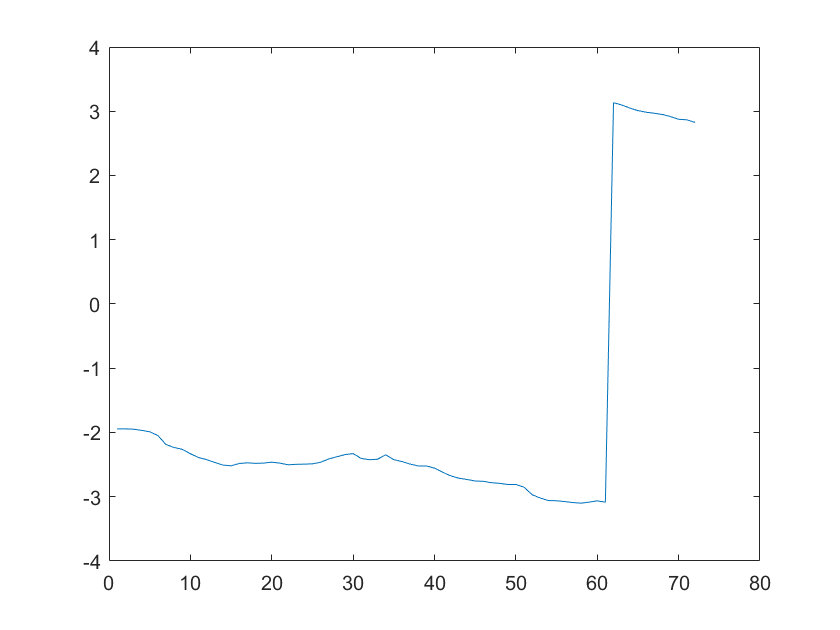

data = load(fname_fit);
circFit = data.circFit;
tr = tracks{1};
[trackCirc1,theta,rkymo]= getTrackAngle(tr,circFit,pixSz);
fr = tr(:,1)+1;
figure;plot(fr,theta,'-');

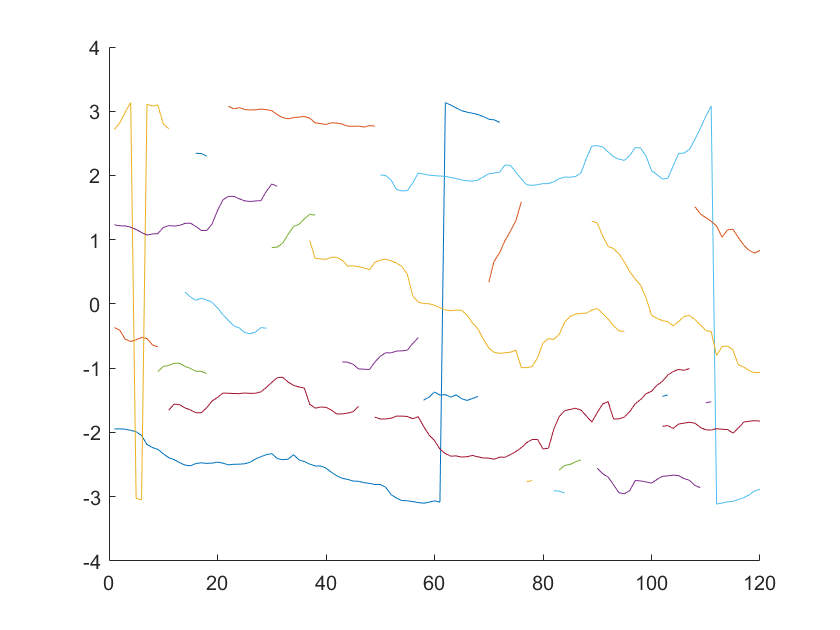


for ii = 1:nTrack
    trackCirc{ii,1}=getTrackAngle(tracks{ii},circFit,pixSz);
end
 
figure;hold all;
for ii = 1:nTrack
    tr = trackCirc{ii,1};
    theta = tr(:,4);
    fr = tr(:,1)+1;
    plot(fr,theta,'-');
end

Looks plausible

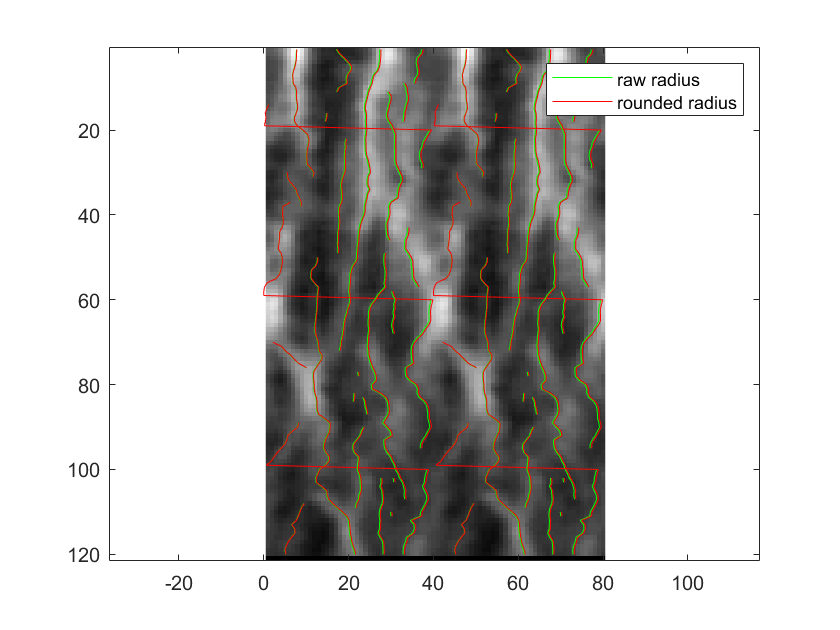

kymo=imread(fname_kymo);
circumference_kymo_im = size(kymo,2);
r_kymo_im = circumference_kymo_im/(2*pi);
% figure;
% imagesc(kymo);
% colormap gray
% axis equal;
% 
% hold all;
% for ii = 1:nTrack
%     tr = trackCirc{ii,1};
%     theta = mod(-tr(:,4)+pi/2,2*pi);
%     c= (theta)*rkymo(1);%constant radius
%     fr = tr(:,1)+1;
%     %plot(c,fr,'x');
%     plot(c,(fr),'rx');
% end

figure;
imagesc([kymo,kymo]);
colormap gray
axis equal;

hold all;
for ii = 1:nTrack
    tr = trackCirc{ii,1};
    theta = mod(tr(:,4),2*pi);
    c1= (theta)*rkymo(1);%constant radius
    c2= (theta)*r_kymo_im;%constant radius
    fr = tr(:,1)+1;
    plot(c1,fr,'g-');
    plot(c2,(fr),'r-');
    plot(c1+circumference_kymo_im,(fr),'g-');
    plot(c2+circumference_kymo_im,fr,'r-');
    
end
legend('raw radius', 'rounded radius')

clearly some teething troubles but not absurd.

There's some offset in the angle the further you get around the ring. What does that imply, innacurate centre?

Also the threshold looks too low which is messing up some of the linking. Could try the intensity wieghted linking

Looks like there ends up being some sort of pixel shift maybe due to inaccurate circle centre - why??

ITs clearly not due to radius rounding issues on the kymograph

try higlighting exampleTrackNo track as above

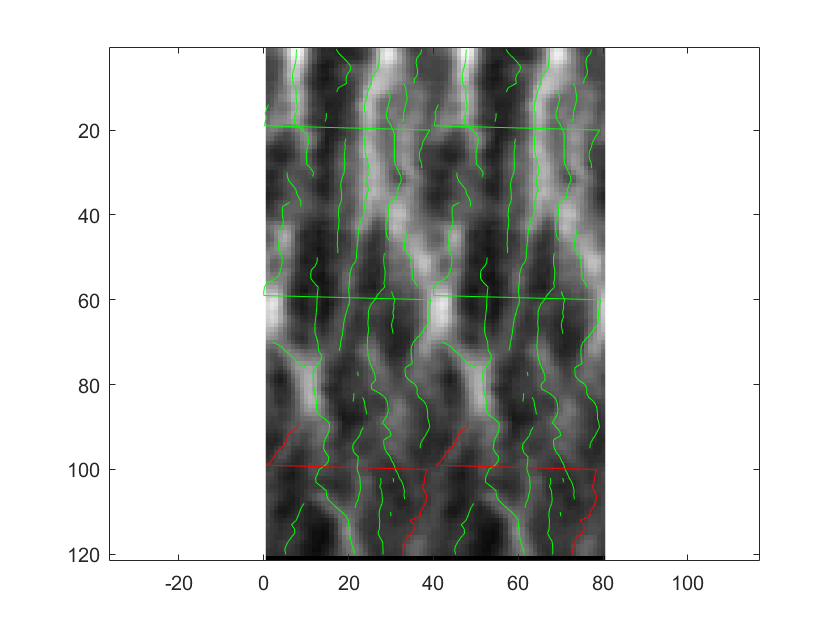

figure;
imagesc([kymo,kymo]);
colormap gray
axis equal;

hold all;
for ii = 1:nTrack
    tr = trackCirc{ii,1};
    theta = mod(tr(:,4),2*pi);
    c1= (theta)*rkymo(1);%constant radius
    fr = tr(:,1)+1;
    if ii == exampleTrackNo
        plot(c1,fr,'r-');
        plot(c1+circumference_kymo_im,(fr),'r-');
    else
        plot(c1,fr,'g-');
        plot(c1+circumference_kymo_im,(fr),'g-');
    end
end

Try instead looking at the localizations in just frame 1 and seeing if we can get them to overlap

Also plot the circle profile see if that makes sense